%calculating the mean first passage time analytically/numerically 
%to investigate effect of invader-substrate mismatche position on DNA/DNA TMSD
%kinetics including spontaneous incumbent dissociation

b = 20 %define branch migration domain length

b = 20

g = 6 %define invader toehold length 

g = 6


R = 1.987/1000 % universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGmm = 9.5*R*temp

dGmm = 5.6280

dGbm = 7.4*R*temp

dGbm = 4.3839

%absolute rate constant
k_bp = 5.9*10^7

k_bp = 59000000

k_eff = zeros(1,19)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 19)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 19)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_eff_perf = zeros(1, 19)

k_eff_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time_perf = zeros(1, 19)

first_pass_time_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound_perf = zeros(1, 19)

prob_unbound_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through mismatch positions
for m = 1:19

    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_Crm = k_bp * exp((dGmm-dGbm)/(R*temp))
    k_CD = k_bp * exp(-dGbm/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    %create arrays of forward and reverse transition rates for
    %mismatch-free system
    Kf_perf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb_perf = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
    %create arrays of forward and reverse transition rates for mismatch
    %systems
    Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    Kb(b-m+1) = k_Crm
    
    %define spontaneous incumbent dissociation rates
    Koff = [0];
    for n = 1:b-1
        Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
    end
    Koff = horzcat(Koff, [repmat(0, [1, g+1])])
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
        
    %calculate flux between each state for mismatch system
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
    end
    
    Pn_jN_1_perf = zeros(1,numel(Kf_perf))
    jn_jN_1_perf = zeros(1,numel(Kf_perf))
    Pn_jN_1_perf (1) = 0;
    jn_jN_1_perf (1) = 1;
        
    %calculate flux between each state for mismatch-free system
    for Pn = 2:numel(Kf)
        Pn_jN_1_perf(Pn)  = 1/Kf_perf(Pn) * jn_jN_1_perf (Pn-1) + (Kb_perf(Pn-1)/Kf_perf(Pn))*Pn_jN_1_perf(Pn-1);
        jn_jN_1_perf(Pn) = jn_jN_1_perf(Pn-1) + Koff(Pn) * Pn_jN_1_perf(Pn);
    end
        
    first_pass_time (m) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %first passage time for mismatch system
    k_eff (m) = 1/(first_pass_time (m)*(5*10^-8)); %effective rate constant for mismatch system
    prob_unbound(m) = Pn_jN_1(end)/sum(Pn_jN_1) %probability of being in unbound state for mismatch system
    
    first_pass_time_perf (m) = (1/jn_jN_1_perf(end-1))*sum(Pn_jN_1_perf) %first passage time for mismatch-free system
    k_eff_perf (m) = 1/(first_pass_time_perf (m)*(5*10^-8)); %effective rate constant for mismatch-free system
    prob_unbound_perf(m) = Pn_jN_1_perf(end)/sum(Pn_jN_1_perf) %prob of being in unbound state for mismatch-free system
end

k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf = 	1.0e+06 *

         0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf = 	1.0e+07 *

    0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb = 	1.0e+06 *

         0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb = 	1.0e+08 *

         0    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    4.8180    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff = 	1.0e+06 *

         0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+04 *

    1.6466         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.2746         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9963         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf = 	1.0e+06 *

         0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf = 	1.0e+07 *

    0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb = 	1.0e+06 *

         0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb = 	1.0e+08 *

         0    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    4.8180    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff = 	1.0e+06 *

         0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+04 *

    1.6466    1.5466         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.2746    6.2746         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9963    0.9963         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf = 	1.0e+06 *

         0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf = 	1.0e+07 *

    0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb = 	1.0e+06 *

         0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb = 	1.0e+08 *

         0    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    4.8180    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff = 	1.0e+06 *

         0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+04 *

    1.6466    1.5466    1.4466         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.2746    6.2746    6.2746         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9963    0.9963    0.9963         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf = 	1.0e+06 *

         0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf = 	1.0e+07 *

    0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    4.8180    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9843         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    4.8180    0.0004    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465    1.2463         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9843    0.9839         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746    6.2746         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963    0.9963         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    4.8180    0.0004    0.0004    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465    1.2463    1.1461         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9843    0.9839    0.9835         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746    6.2746    6.2746         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963    0.9963    0.9963         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    4.8180    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465    1.2463    1.1461    1.0458         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9843    0.9839    0.9835    0.9832         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    4.8180    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465    1.2463    1.1461    1.0458    0.9454         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9843    0.9839    0.9835    0.9832    0.9828         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    4.8180    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465    1.2463    1.1461    1.0458    0.9454    0.8449         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9843    0.9839    0.9835    0.9832    0.9828    0.9824         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    4.8180    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465    1.2463    1.1461    1.0458    0.9454    0.8449    0.7443         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9843    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    4.8180    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465    1.2463    1.1461    1.0458    0.9454    0.8449    0.7443    0.6427         0         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9843    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817         0         0         0         0         0         0         0         0


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963         0         0         0         0         0         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    4.8180    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465    1.2463    1.1461    1.0458    0.9454    0.8449    0.7443    0.6427    0.5335         0         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9843    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814         0         0         0         0         0         0         0


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746         0         0         0         0         0         0         0


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963         0         0         0         0         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    4.8180    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465    1.2463    1.1461    1.0458    0.9454    0.8449    0.7443    0.6427    0.5335    0.3741         0         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9843    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814    0.9810         0         0         0         0         0         0


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746         0         0         0         0         0         0


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963         0         0         0         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    0.0004    0.0004    0.0004    0.0004    0.0004    4.8180    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465    1.2463    1.1461    1.0458    0.9454    0.8449    0.7443    0.6427    0.5335    0.3741    0.1245         0         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9843    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814    0.9810    0.9807         0         0         0         0         0


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746         0         0         0         0         0


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963         0         0         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    0.0004    0.0004    0.0004    0.0004    4.8180    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465    1.2463    1.1461    1.0458    0.9454    0.8449    0.7443    0.6427    0.5335    0.3741    0.1245    0.0153         0         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9843    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814    0.9810    0.9807    0.9809         0         0         0         0


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746         0         0         0         0


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963         0         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    0.0004    0.0004    0.0004    4.8180    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465    1.2463    1.1461    1.0458    0.9454    0.8449    0.7443    0.6427    0.5335    0.3741    0.1245    0.0153    0.0019         0         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9843    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814    0.9810    0.9807    0.9809    0.9855         0         0         0


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746         0         0         0


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963         0         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    0.0004    0.0004    4.8180    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465    1.2463    1.1461    1.0458    0.9454    0.8449    0.7443    0.6427    0.5335    0.3741    0.1245    0.0153    0.0019    0.0007         0         0


prob_unbound =     0.9853    0.9850    0.9846    0.9843    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814    0.9810    0.9807    0.9809    0.9855    0.9942         0         0


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746         0         0


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963         0         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    0.0004    4.8180    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465    1.2463    1.1461    1.0458    0.9454    0.8449    0.7443    0.6427    0.5335    0.3741    0.1245    0.0153    0.0019    0.0007    0.0006         0


prob_unbound =     0.9853    0.9850    0.9846    0.9843    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814    0.9810    0.9807    0.9809    0.9855    0.9942    0.9962         0


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746         0


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963         0


k_AB1 = 0.2191

k_B1A = 4.7471e+06

k_C1f = 985.4003

k_Cf = 3.6064e+04

k_Crm = 4.8180e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb_perf =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kf =     0.0000    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0001    5.9000    5.9000    5.9000    5.9000    5.9000    0.0000


Kb =          0    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    0.0361    4.7471    4.7471    4.7471    4.7471    4.7471    4.7471         0


Kb =          0    4.8180    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0475    0.0475    0.0475    0.0475    0.0475    0.0475         0


Koff =          0    4.7471    0.3820    0.0307    0.0025    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.6466    1.5466    1.4466    1.3465    1.2463    1.1461    1.0458    0.9454    0.8449    0.7443    0.6427    0.5335    0.3741    0.1245    0.0153    0.0019    0.0007    0.0006    0.0006


prob_unbound =     0.9853    0.9850    0.9846    0.9843    0.9839    0.9835    0.9832    0.9828    0.9824    0.9821    0.9817    0.9814    0.9810    0.9807    0.9809    0.9855    0.9942    0.9962    0.9963


first_pass_time_perf =     6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746    6.2746


prob_unbound_perf =     0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963


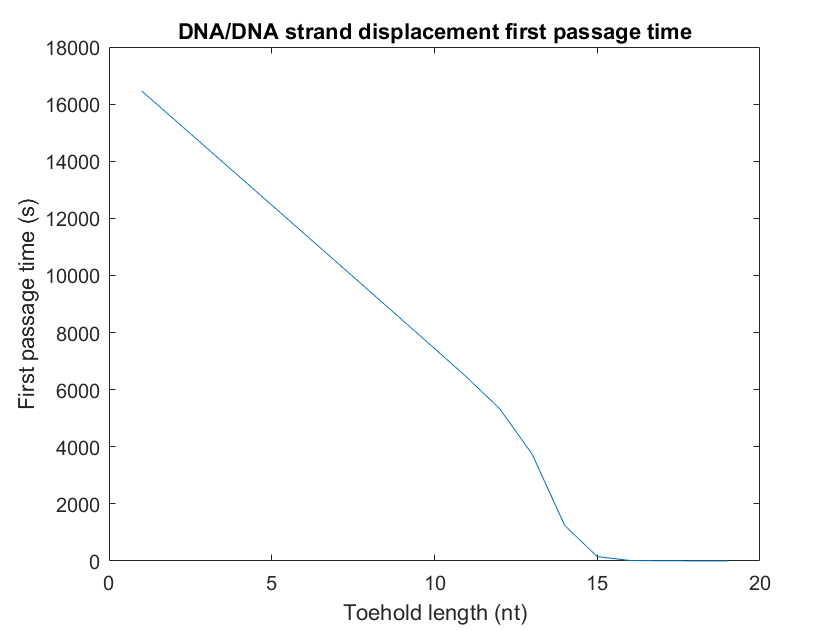

plot(1:19, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

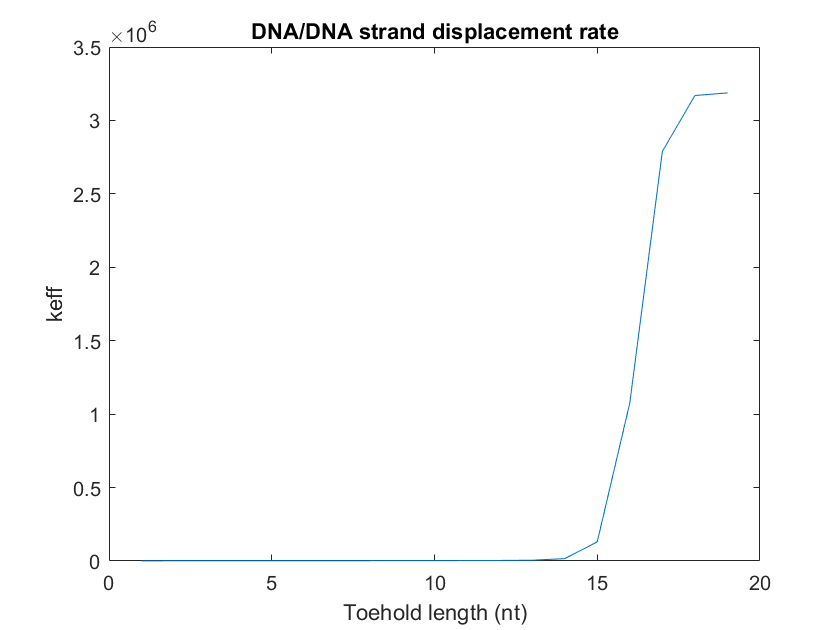


plot(1:19, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

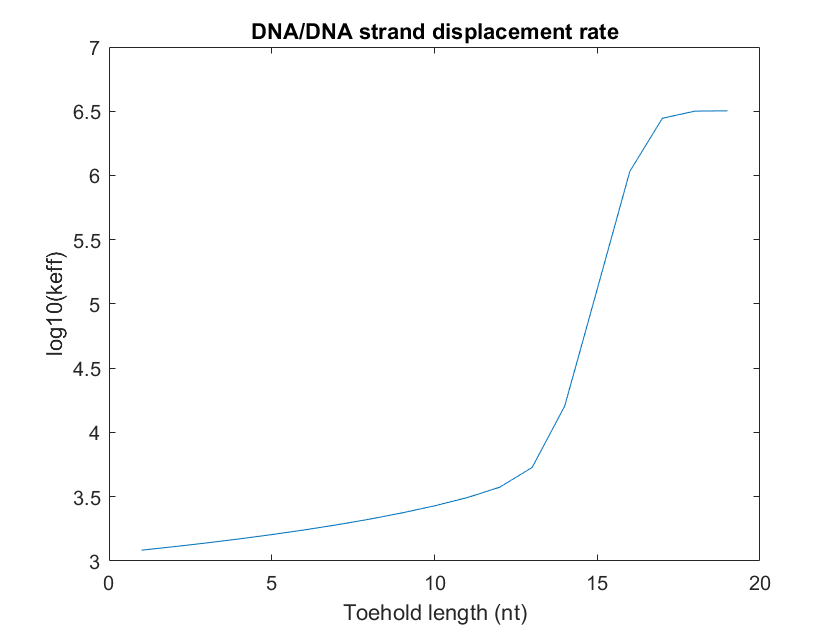


plot(1:19, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  

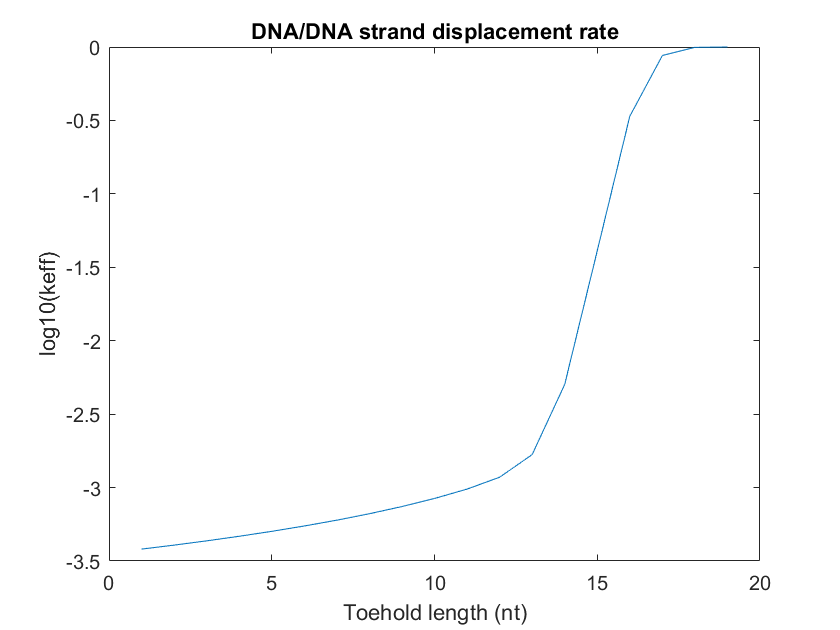


plot(1:19, log10(k_eff./k_eff_perf))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  